# Feature Extraction Using AlexNet

此代码说明如何从预训练的卷积神经网络中提取已学习的图像特征，并使用这些特征来训练图像分类器.特征提取是使用预训练深度网络的表征能力的最简单最快捷的方式。

## **加载数据**

首先将源数据中的掩模图像转化为jpg然后根据临床数据中的淋巴结转移的阴阳划分为两个文件夹。然后加载图像作为图像数据存储.`imageDatastore`根据文件夹名称自动标记图像，并将数据存储为`ImageDatastore`对象.通过图像数据存储可以存储大图像数据，包括无法放入内存的数据.将数据拆分，其中70%用作训练数据，30%用作测试数据。

unzip('BShiLiYanMo.zip');
imds = imageDatastore('BShiLiYanMo', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

[imdsTrain,imdsTest] = splitEachLabel(imds,0.7,'randomized');

在这个数据集中，.显示一些示例图像.

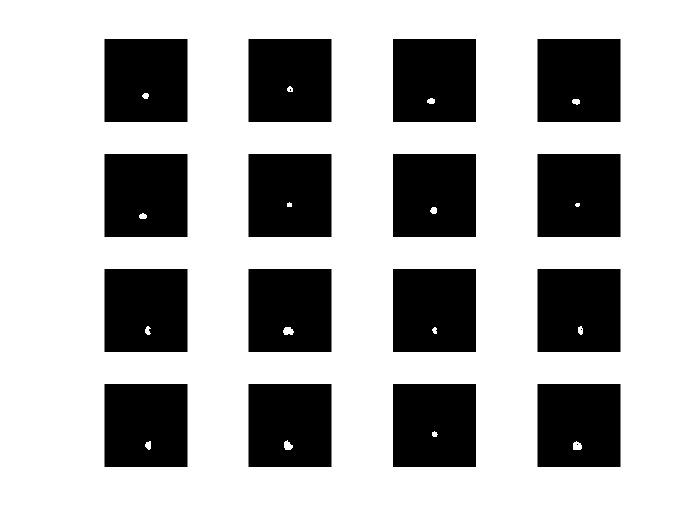

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

## **加载预训练网络**

加载预训练的AlexNet网络.如果未安装深度学习工具箱模型*为AlexNet网络*支持包，则软件会提供下载链接.AlexNet已基于超过一百万个图像进行训练，可以将图像分为1000个对象类别.例如，键盘、鼠标、铅笔和多种动物.因此，该模型已基于大量图像学习了丰富的特征表示.

net = alexnet;

显示网络架构.该网络有五个卷积层和三个全连接层

net.Layers

ans =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    10 

第一层(图像输入层)需要大小为227×227×3的输入图像，其中3是颜色通道数

inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


## **提取图像特征**

网络构造输入图像的分层表示.更深层包含更高级别的特征，这些特征使用较浅层的较低级别特征构建.要获得训练图像和测试图像的特征表示，请对全连接层`'fc7'`使用`activations`..要获得图像的较低级别表示，请使用网络中的较浅层.

网络要求输入图像的大小为227×227×3，但图像数据存储中的图像具有不同大小。要在将训练图像和测试图像输入到网络之前自动调整它们的大小，请创建增强的图像数据存储，指定所需的图像大小，并将这些数据存储用作`activations`的输入参数.

augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

layer = 'fc7';
featuresTrain = activations(net,augimdsTrain,layer,'OutputAs','rows');

错误使用 SeriesNetwork/activations (line 809)
The input images for activations must be of size equal to or greater than [227 227 3].

featuresTest = activations(net,augimdsTest,layer,'OutputAs','rows');

从训练数据和测试数据中提取类标签.

YTrain = imdsTrain.Labels;
YTest = imdsTest.Labels;

## **拟合图像分类器**

使用从训练图像中提取的特征作为预测变量，并使用`fitcecoc`(统计和机器学习工具箱)拟合多类支持向量机(支持向量机)

classifier = fitcecoc(featuresTrain,YTrain);

## **对测试图像进行分类**

使用经过训练的支持向量机模型和从测试图像中提取的特征对测试图像进行分类.

YPred = predict(classifier,featuresTest);

显示四个示例测试图像及预测的标签..

idx = [1 5 10 15];
figure
for i = 1:numel(idx)
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    label = YPred(idx(i));
    imshow(I)
    title(char(label))
end

计算针对测试集的分类准确度.准确度是网络预测正确的标签的比例.

accuracy = mean(YPred == YTest)